# Test Case - Power Split Drive Unit

mdl = "PowerSplitDriveUnit_Component_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end
PowerSplitDriveUnit_Component_harness_setup

## Setup

simIn = Simulink.SimulationInput(mdl);

% Block parameters

simIn = setBlockParameter(simIn, mdl+"/Road grade", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Road grade", Time="1");
simIn = setBlockParameter(simIn, mdl+"/Road grade", After="0");

simIn = setBlockParameter(simIn, mdl+"/Brake force", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Brake force", Time="1");
simIn = setBlockParameter(simIn, mdl+"/Brake force", After="0");

simIn = setBlockParameter(simIn, mdl+"/MG2 torque command", Before="0");
simIn = setBlockParameter(simIn, mdl+"/MG2 torque command", Time="1");
simIn = setBlockParameter(simIn, mdl+"/MG2 torque command", After="0");

simIn = setBlockParameter(simIn, mdl+"/MG1 torque command", Before="0");
simIn = setBlockParameter(simIn, mdl+"/MG1 torque command", Time="1");
simIn = setBlockParameter(simIn, mdl+"/MG1 torque command", After="0");

simIn = setBlockParameter(simIn, mdl+"/Engine torque command", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Engine torque command", Time="1");
simIn = setBlockParameter(simIn, mdl+"/Engine torque command", After="0");

% Initial conditions

simIn = setVariable(simIn, "initial.vehicle_speed_kph", 0);

simIn = setVariable(simIn, "initial.engine_speed_rpm", 0);

simIn = setVariable(simIn, "initial.MG1_Temperature_degC", 20);
simIn = setVariable(simIn, "initial.MG1_AirTemp_degC", 20);

simIn = setVariable(simIn, "initial.MG2_Temperature_degC", 20);
simIn = setVariable(simIn, "initial.MG2_AirTemp_degC", 20);

## Run Simulation

% Simulaton stop time
simIn = setModelParameter(simIn, StopTime = "1000");

% Run simulation
simOut = sim(simIn);

## Visualize Simulation Result

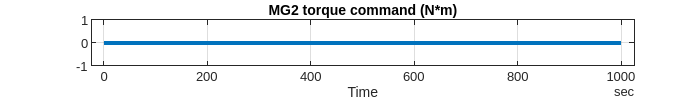

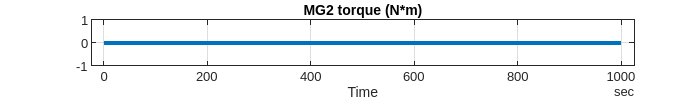

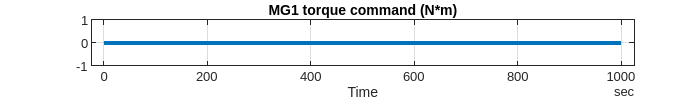

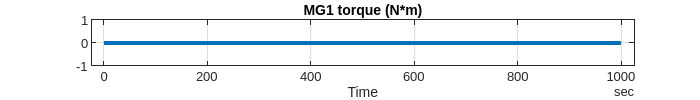

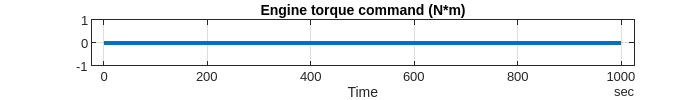

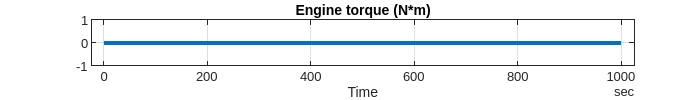

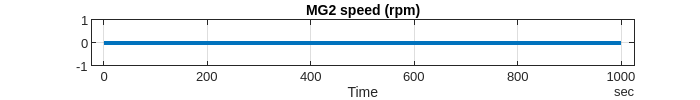

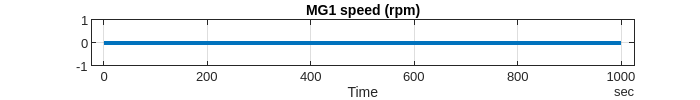

simData = extractTimetable(simOut.logsout);

PowerSplitDriveUnit_Component_plotResults(SimData = simData, FigureHeight = 100);

*Copyright 2021-2022 The Mathworks, Inc.*